# **Medición del Gap de Energía del Si y Ge**

clear all %limpiamos el workspace
clear axes 

Importamos los datos obtenidos experimentalmente:

Data_Ex1_Si = xlsread("Datos Laboratorio 6.xlsx",1); % Archivo excel.
Data_Ex1_Ge = xlsread("Datos Laboratorio 6.xlsx",2);
Data_Ex2_Si = xlsread("Datos Laboratorio 6.xlsx",3);
Data_Ex2_Ge = xlsread("Datos Laboratorio 6.xlsx",4);

Definimos las contantes a usar en el experimento

e = 1.6*10^-19;
Kb = 1.38*10^-23;
Temp_ambiente = 300;
elec_volt = 1.602*10^-19;

## Experimento 1: Polarización directa

### ***Silicio:***

Para el silicio tenemos 2 mediciones de datos. Para la 1era tenemos:

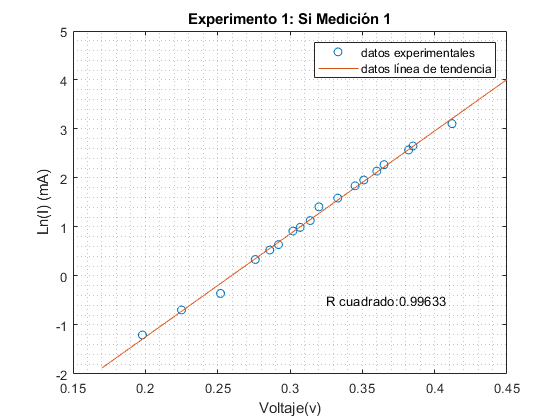

Ln_I_exp1_Si = log(Data_Ex1_Si(:,1));
p=polyfit(Data_Ex1_Si(:,2),Ln_I_exp1_Si,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m1Si= p(1);
tend_x = linspace(0.17,0.45,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Data_Ex1_Si(:,2),Ln_I_exp1_Si,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.

yfit = polyval(p,Data_Ex1_Si(:,2));
yfit =  p(1) * Data_Ex1_Si(:,2) + p(2);
yresid = Ln_I_exp1_Si - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp1_Si)-1) * var(Ln_I_exp1_Si);
rsq_exp1_Si = 1 - SSresid/SStotal;

%procedemos a etiquetar la tabla
title('Experimento 1: Si Medición 1')
ylabel('Ln(I) (mA)')
xlabel('Voltaje(v)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(0.325,-0.5,strcat('R cuadrado:', num2str(rsq_exp1_Si)),'Color', 'black');

Ahora procedemos a hallar el factor de idealidad del silicio:

m1Si_1= p(1);% pendiente del ajuste lineal.
n_Si_1 = e/(m1Si_1*Kb*Temp_ambiente)

n_Si_1 = 1.8377

Para la 2da tenemos:

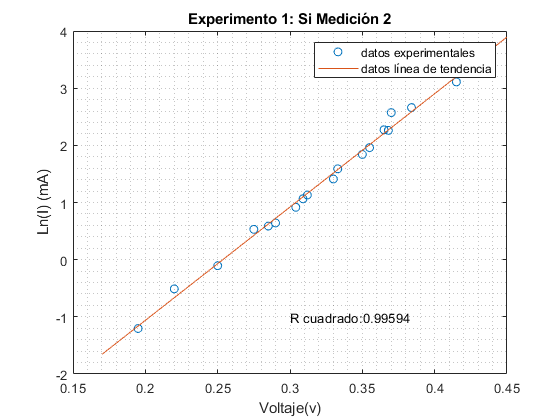

Ln_I_exp1_Si = log(Data_Ex1_Si(:,3));
p=polyfit(Data_Ex1_Si(:,4),Ln_I_exp1_Si,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m1Si= p(1);
tend_x = linspace(0.17,0.45,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Data_Ex1_Si(:,4),Ln_I_exp1_Si,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.
yfit = polyval(p,Data_Ex1_Si(:,2));
yfit =  p(1) * Data_Ex1_Si(:,2) + p(2);
yresid = Ln_I_exp1_Si - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp1_Si)-1) * var(Ln_I_exp1_Si);
rsq_exp1_Si = 1 - SSresid/SStotal;
%procedemos a etiquetar la tabla
title('Experimento 1: Si Medición 2')
ylabel('Ln(I) (mA)')
xlabel('Voltaje(v)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(0.3,-1,strcat('R cuadrado:', num2str(rsq_exp1_Si)),'Color', 'black');

Ahora procedemos a hallar el factor de idealidad del silicio:

m1Si_2= p(1);% pendiente del ajuste lineal.
n_Si_2 = e/(m1Si_2*Kb*Temp_ambiente)

n_Si_2 = 1.9491

Entonces, procedemos a hallar el n a partir del promedio de ambos procesos:

n_Si = (n_Si_1+n_Si_2)/2

n_Si = 1.8934

### ***Germanio:***

Para el germanio tenemos:

Para el Germanio tenemos 2 mediciones de datos. Para la 1era tenemos:

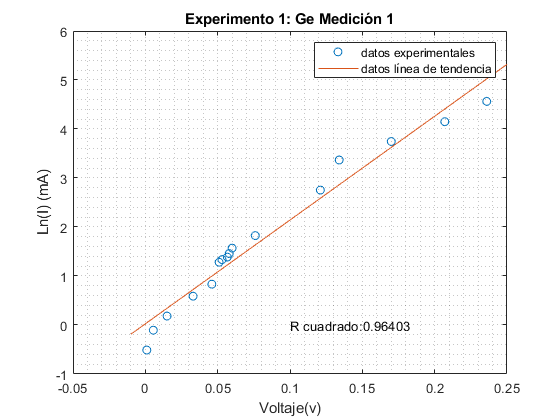

Ln_I_exp1_Ge = log(Data_Ex1_Ge(:,1));
p=polyfit(Data_Ex1_Ge(:,2),Ln_I_exp1_Ge,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m1Ge= p(1);
tend_x = linspace(-0.01,0.25,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Data_Ex1_Ge(:,2),Ln_I_exp1_Ge,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.

yfit = polyval(p,Data_Ex1_Ge(:,2));
yfit =  p(1) * Data_Ex1_Ge(:,2) + p(2);
yresid = Ln_I_exp1_Ge - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp1_Ge)-1) * var(Ln_I_exp1_Ge);
rsq_exp1_Ge = 1 - SSresid/SStotal;

%procedemos a etiquetar la tabla
title('Experimento 1: Ge Medición 1')
ylabel('Ln(I) (mA)')
xlabel('Voltaje(v)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(0.1,0,strcat('R cuadrado:', num2str(rsq_exp1_Ge)),'Color', 'black');

Ahora procedemos a hallar el factor de idealidad del Germanio:

m1Ge_1= p(1);% pendiente del ajuste lineal.
n_Ge_1 = e/(m1Ge_1*Kb*Temp_ambiente)

n_Ge_1 = 1.8245

Para la 2da tenemos:

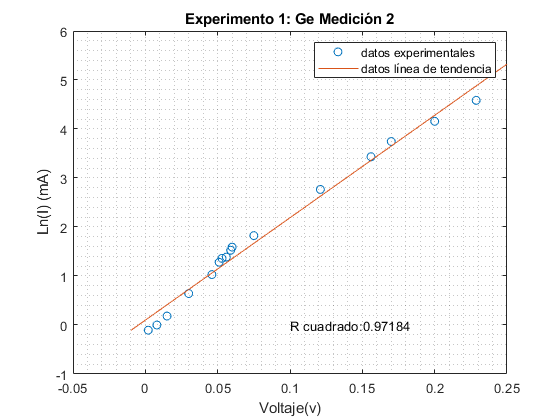

Ln_I_exp1_Ge = log(Data_Ex1_Ge(:,3));
p=polyfit(Data_Ex1_Ge(:,4),Ln_I_exp1_Ge,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m1Ge= p(1);
tend_x = linspace(-0.01,0.25,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Data_Ex1_Ge(:,4),Ln_I_exp1_Ge,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.
yfit = polyval(p,Data_Ex1_Ge(:,2));
yfit =  p(1) * Data_Ex1_Ge(:,2) + p(2);
yresid = Ln_I_exp1_Ge - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp1_Ge)-1) * var(Ln_I_exp1_Ge);
rsq_exp1_Ge = 1 - SSresid/SStotal;
%procedemos a etiquetar la tabla
title('Experimento 1: Ge Medición 2')
ylabel('Ln(I) (mA)')
xlabel('Voltaje(v)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(0.1,0,strcat('R cuadrado:', num2str(rsq_exp1_Ge)),'Color', 'black');

Ahora procedemos a hallar el factor de idealidad del Germanio:

m1Ge_2= p(1);% pendiente del ajuste lineal.
n_Ge_2 = e/(m1Ge_2*Kb*Temp_ambiente)

n_Ge_2 = 1.8491

Entonces, procedemos a hallar el n a partir del promedio de ambos procesos:

n_Ge = (n_Ge_1+n_Ge_2)/2

n_Ge = 1.8368

## Experimento 2: Polarización inversa

Antes, es necesaria una aclaración:

De la ecuacion de la corriente inversa, podemos tener lo siguiente:

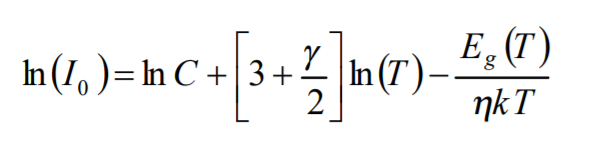

Ahora, considerando que la curvatura introducida producto de la dependencia logaritmica es despreciable (ya que tenemos temperaturas superiores a los 125 grados) podemos considerar que la pendiente de la linealización de 1/T vs Ln(I_0) será E_g/nK_b.

Entonces tenemos: 

### ***Silicio:***

Para el silicio tenemos 2 mediciones de datos. Para la 1era tenemos:

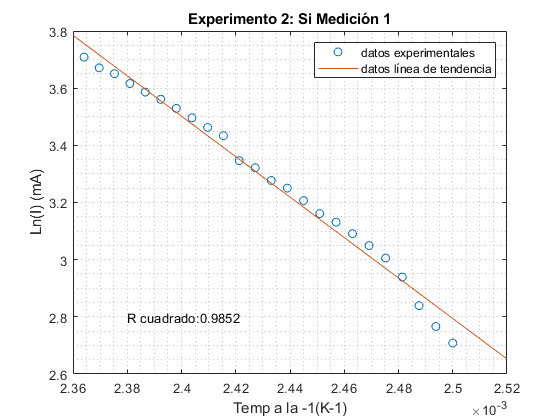

Ln_I_exp2_Si = log(Data_Ex2_Si(:,1));
Temp_kelvin = 273 + Data_Ex2_Si(:,2);
Temp_inv_exp2_Si = 1./Temp_kelvin;

p=polyfit(Temp_inv_exp2_Si,Ln_I_exp2_Si,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m2Si_1 = p(1);
tend_x = linspace(2.36*10^-3,2.52*10^-3,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Temp_inv_exp2_Si,Ln_I_exp2_Si,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.

yfit = polyval(p,Temp_inv_exp2_Si);
yfit =  p(1) * Temp_inv_exp2_Si + p(2);
yresid = Ln_I_exp2_Si - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp2_Si)-1) * var(Ln_I_exp2_Si);
rsq_exp2_Si = 1 - SSresid/SStotal;

%procedemos a etiquetar la tabla
title('Experimento 2: Si Medición 1')
ylabel('Ln(I) (mA)')
xlabel('Temp a la -1(K-1)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(2.38*10^-3,2.8,strcat('R cuadrado:', num2str(rsq_exp2_Si)),'Color', 'black');

Ahora, procedemos a hallar el Gap usando el n hallado en el exp anterior:

E_gap_Si_1 = m2Si_1*n_Si*Kb/elec_volt

E_gap_Si_1 = -1.1539

Ahora, para la 2da medición de datos tenemos que :

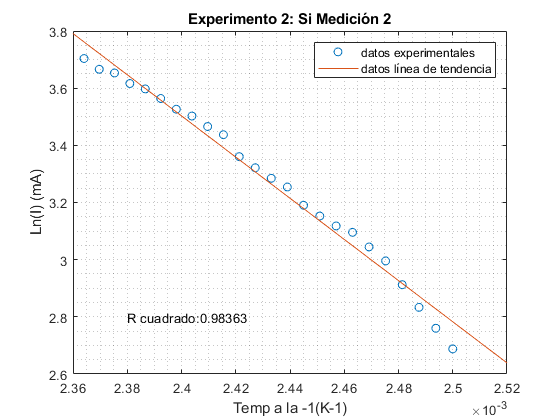

Ln_I_exp2_Si = log(Data_Ex2_Si(:,3));
Temp_kelvin = 273 + Data_Ex2_Si(:,4);
Temp_inv_exp2_Si = 1./Temp_kelvin;

p=polyfit(Temp_inv_exp2_Si,Ln_I_exp2_Si,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m2Si_2 = p(1);
tend_x = linspace(2.36*10^-3,2.52*10^-3,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Temp_inv_exp2_Si,Ln_I_exp2_Si,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.

yfit = polyval(p,Temp_inv_exp2_Si);
yfit =  p(1) * Temp_inv_exp2_Si + p(2);
yresid = Ln_I_exp2_Si - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp2_Si)-1) * var(Ln_I_exp2_Si);
rsq_exp2_Si = 1 - SSresid/SStotal;

%procedemos a etiquetar la tabla
title('Experimento 2: Si Medición 2')
ylabel('Ln(I) (mA)')
xlabel('Temp a la -1(K-1)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(2.38*10^-3,2.8,strcat('R cuadrado:', num2str(rsq_exp2_Si)),'Color', 'black');

Ahora, procedemos a hallar el Gap usando el n hallado en el exp anterior:

E_gap_Si_2 = m2Si_2*n_Si*Kb/elec_volt

E_gap_Si_2 = -1.1745

Entonces, procedemos a hallar el Gap final a partir del promedio de ambas:

E_gap_Si = (E_gap_Si_1 + E_gap_Si_2)/2

E_gap_Si = -1.1642

ahora, tomando como valor referencial:

E_si_ref = -1.12;

Tenemos entonces el error porcentual:

Error = 100*abs((E_gap_Si-E_si_ref)/E_si_ref)

Error = 3.9498

### ***Germanio:***

Para el Germanio tenemos 2 mediciones de datos. Para la 1era tenemos:

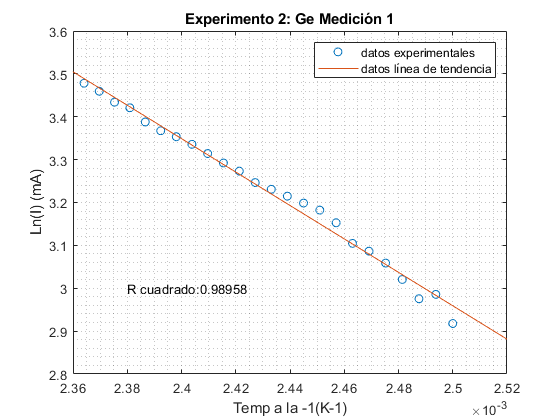

Ln_I_exp2_Ge = log(Data_Ex2_Ge(:,1));
Temp_kelvin = 273 + Data_Ex2_Ge(:,2);
Temp_inv_exp2_Ge = 1./Temp_kelvin;

p=polyfit(Temp_inv_exp2_Ge,Ln_I_exp2_Ge,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m2Ge_1 = p(1);
tend_x = linspace(2.36*10^-3,2.52*10^-3,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Temp_inv_exp2_Ge,Ln_I_exp2_Ge,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.

yfit = polyval(p,Temp_inv_exp2_Ge);
yfit =  p(1) * Temp_inv_exp2_Ge + p(2);
yresid = Ln_I_exp2_Ge - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp2_Ge)-1) * var(Ln_I_exp2_Ge);
rsq_exp2_Ge = 1 - SSresid/SStotal;

%procedemos a etiquetar la tabla
title('Experimento 2: Ge Medición 1')
ylabel('Ln(I) (mA)')
xlabel('Temp a la -1(K-1)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(2.38*10^-3,3,strcat('R cuadrado:', num2str(rsq_exp2_Ge)),'Color', 'black');

Ahora, procedemos a hallar el Gap usando el n hallado en el exp anterior:

E_gap_Ge_1 = m2Ge_1*n_Ge*Kb/elec_volt

E_gap_Ge_1 = -0.6167

Ahroa, para la 2da trama de datos tenemos que :

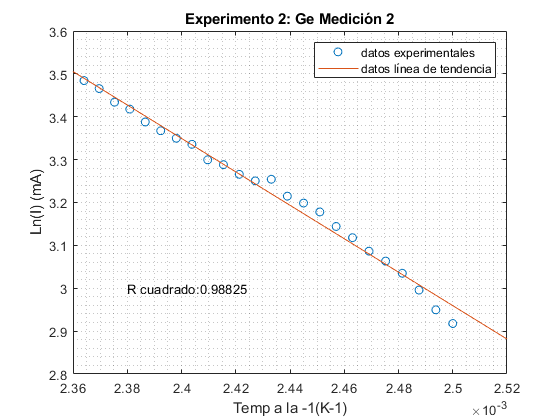

Ln_I_exp2_Ge = log(Data_Ex2_Ge(:,3));
Temp_kelvin = 273 + Data_Ex2_Ge(:,4);
Temp_inv_exp2_Ge = 1./Temp_kelvin;

p=polyfit(Temp_inv_exp2_Ge,Ln_I_exp2_Ge,1); % realiza el ajuste lineal en las matrices que contiene los datos y nos da los coeficientes de la función de tendencia.
m2Ge_2 = p(1);
tend_x = linspace(2.36*10^-3,2.52*10^-3,1000); %definimos el dominio en la línea de tendencia.
tend_y = polyval(p,tend_x); %obtenemos el valor del rango de la línea de tencia, al evaluar los valores del dominio en p.

plot(Temp_inv_exp2_Ge,Ln_I_exp2_Ge,'o');
hold on
plot(tend_x,tend_y)
% Ahora procedemos a hallar el R cuadrado del analisis.

yfit = polyval(p,Temp_inv_exp2_Ge);
yfit =  p(1) * Temp_inv_exp2_Ge + p(2);
yresid = Ln_I_exp2_Ge - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(Ln_I_exp2_Ge)-1) * var(Ln_I_exp2_Ge);
rsq_exp2_Ge = 1 - SSresid/SStotal;

%procedemos a etiquetar la tabla
title('Experimento 2: Ge Medición 2')
ylabel('Ln(I) (mA)')
xlabel('Temp a la -1(K-1)')
legend('datos experimentales','datos línea de tendencia')
grid minor
hold off
text(2.38*10^-3,3,strcat('R cuadrado:', num2str(rsq_exp2_Ge)),'Color', 'black');

Ahora, procedemos a hallar el Gap usando el n hallado en el exp anterior:

E_gap_Ge_2 = m2Ge_2*n_Ge*Kb/elec_volt

E_gap_Ge_2 = -0.6171

Entonces, procedemos a hallar el Gap final a partir del promedio de ambas:

E_gap_Ge = (E_gap_Ge_1 + E_gap_Ge_2)/2

E_gap_Ge = -0.6169

ahora, tomando como valor referencial:

E_Ge_ref = -0.66;

Tenemos entonces el error porcentual:

Error = 100*abs((E_gap_Ge-E_Ge_ref)/E_Ge_ref)

Error = 6.5266